% Q7:

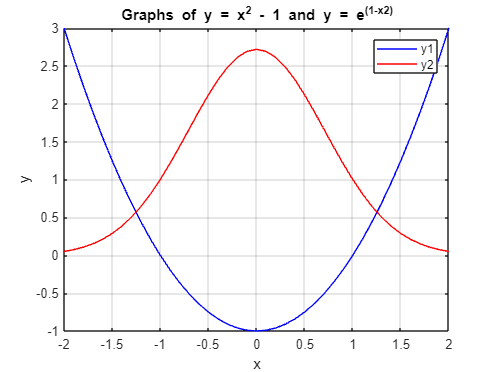

x = -2:0.1:2;       y1 = x.^2 - 1;      y2 = exp(1 - x.^2);

figure; plot(x, y1, 'b', x, y2, 'r'); xlabel('x'); ylabel('y');
title('Graphs of y = x^2 - 1 and y = e^(1-x^2)');
legend('y1', 'y2'); grid on;

f = @(x) x.^2 - 1 - exp(1 - x.^2);

if f(-2) * f(0) > 0
    disp('The function does not change sign, so we can use bisection');
else
    
    a = -2;     b = 0;      tol = 1e-3;

    while (b - a) > tol
        c = (a + b) / 2; % mid
        if f(c) == 0
            break; % c is root
        elseif f(c) * f(a) < 0
            b = c; %root before c
        else
            a = c; %root before c
        end
    end

    disp(['ANS to q7 is x = ', num2str(c)]);

end

ANS to q7 is x = -1.251


% Q8:

n = 0;      p = 0;

n_values = [];
p_prev_values = [];     p_values = [];      abs_diff_values = [];

for i = 1:16
    p_prev = p;     p = sqrt(exp(p_prev) / 3);       n=n+1;
    n_values = [n_values; n];    p_prev_values = [p_prev_values; p_prev];
    p_values = [p_values; p];    abs_diff_values = [abs_diff_values; abs(p - p_prev)];
end

% make table
T = table(n_values, p_prev_values, p_values, abs_diff_values, 'VariableNames', {'n', 'p(n-1)', 'p(n)', '|p(n) - p(n-1)|'});
disp(T);

    n     p(n-1)      p(n)      |p(n) - p(n-1)|
    __    _______    _______    _______________

     1          0    0.57735         0.57735   
     2    0.57735    0.77057         0.19321   
     3    0.77057    0.84872        0.078157   
     4    0.84872    0.88255        0.033823   
     5    0.88255     0.8976        0.015052   
     6     0.8976    0.90438       0.0067809   
     7    0.90438    0.90745       0.0030715   
     8    0.90745    0.90884       0.0013947   
     9    0.90884    0.90948      0.00063399   
    10    0.90948    0.90977      0.00028835   
    11    0.90977     0.9099      0.00013117   
    12     0.9099    0.90996      5.9679e-05   
    13    0.90996    0.90998      2.7153e-05   
    14    0.90998       0.91      1.2355e-05   
    15       0.91       0.91      5.6213e-06   
    16       0.91    0.91001      2.5577e-06   

% Therefore: the required fixed point is 0.91000

% Q9:

f = @(x) (x-2)^2 - log(x);      df = @(x) 2*(x-2) - 1/x;
x0 = 1.5;       tol = 1e-5;

x = x0;     i = 0;
while abs(f(x)) > tol
    x = x - f(x) / df(x);       i=i+1;
    if (x <= 1 || x >= 2) && (x <= exp(1) || x >= 4)
        break; %% leaving range
    end
end

disp(['ans 6d in range 1 is x = ', num2str(x), ' after ', num2str(i), ' iterations.']);

ans 6d in range 1 is x = 1.4124 after 3 iterations.



f = @(x) (x-2)^2 - log(x);      df = @(x) 2*(x-2) - 1/x;
x0 = 3.1;       tol = 1e-5;

x = x0;     i = 0;
while abs(f(x)) > tol
    x = x - f(x) / df(x);       i=i+1;
    if (x <= exp(1) || x >= 4)
        break; %% leaving range
    end
end

disp(['ans 6d in range 2 is x = ', num2str(x), ' after ', num2str(i), ' iterations.']);

ans 6d in range 2 is x = 3.0571 after 2 iterations.


f = @(x) (x-2)^2 - log(x);
x0 = 1.5;        x1 = 1.8;       tol = 1e-5;     i = 0;

while abs(f(x1)) > tol
    x2 = x1 - f(x1) * (x1 - x0) / (f(x1) - f(x0));
    x0 = x1;        x1 = x2;        i = i + 1;
    if (x2 <= 1 || x2 >= 2) && (x2 <= exp(1) || x2 >= 4)
        break; %% leaving range
    end
end

disp(['ans 8d in range 1 is x = ', num2str(x2), ' after ', num2str(i), ' iterations.']);

ans 8d in range 1 is x = 1.4124 after 4 iterations.



f = @(x) (x-2)^2 - log(x);
x0 = 3.1;        x1 = 1.8;       tol = 1e-5;     i = 0;

while abs(f(x1)) > tol
    x2 = x1 - f(x1) * (x1 - x0) / (f(x1) - f(x0));
    x0 = x1;        x1 = x2;        i = i + 1;
    if (x2 <= exp(1) || x2 >= 4)
        break; %% leaving range
    end
end

disp(['ans 8d in range 2 is x = ', num2str(x2), ' after ', num2str(i), ' iterations.']);

ans 8d in range 2 is x = 3.0571 after 6 iterations.
